# Preliminaries

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

It is necessary to have access to thermodynamic data. This curriculum module is built with [CoolProp](http://www.coolprop.org/). [1]

You can access the code on GitHub: [`https://github.com/CoolProp/CoolProp`](https://github.com/CoolProp/CoolProp)

## Getting ready

### Step 1: Check your MATLAB version 

The code that allows accessing CoolProp works by using both MATLAB and Python. What version of MATLAB are you running?

releaseInfo = matlabRelease;
str = "This is release " + releaseInfo.Release + ",";
if isMATLABReleaseOlderThan("R2021a")
    disp(str + " so it may not run this example.")
else
    disp(str + " so you can proceed with this script.")
end

### Step 2: Check your Python version

You must have Python installed, and it must be a [supported version of Python](https://www.mathworks.com/content/dam/mathworks/mathworks-dot-com/support/sysreq/files/python-compatibility.pdf) for your MATLAB version. For R2022b, for instance, you need to use Python 3.8 or 3.9. What version are you using?

localCheckPythonVersion;

If you do not have a supported version of Python installed, follow the instructions in the [documentation to install and select](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html) a supported version. If you have a supported version of Python installed, but it is not on your MATLAB path, you will need to add it using `addpath`

The output will be a file path, something like:

`C:\Users\yourname\AppData\Local\Programs\Python\Python39\python.exe`

You can add this to your MATLAB path by running

### Step 3: Download CoolProp from GitHub

You can find the **Home** tab of the toolstrip and select **New**. In that dropdown menu, select **Project** and then **From Git**. Type or paste the address  [https://github.com/CoolProp/CoolProp.git](https://github.com/CoolProp/CoolProp.git) into the **Repository Path** field:

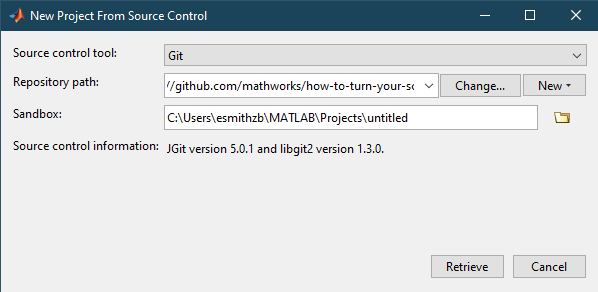

If you want, you can change the Sandbox location. It would be best if you changed the folder name from untitled to something more descriptive, such as CoolProp. If you are in MATLAB Online, you will need to select a MATLAB Drive location. Then select **Retrieve**. If the folder identified as the Sandbox does not exist, you will be prompted to create it.  

  **Pro-tip**. If you have a command-line Git installation, you can uncomment and run the following to download the Live Task.

% !git clone https://github.com/CoolProp/CoolProp.git

### Step 4: Install numpy and CoolProp

If you have `pip`, you can run

!pip install numpy
!pip install CoolProp

### Step 5: Add CoolProp to your MATLAB path

Switch directories into the CoolProp folder you created in Step 3. Add all folders and subfolders to your MATLAB path by running the following:

addpath(genpath(pwd))

### Step 6: Test your installation

Then switch back to the Thermodynamics folder. To check that CoolProp is installed and accessible, run the test suite:

run(CoolPropWrapperTests)

### Step 7: Check that you can query CoolProp

You can learn more about the [substances included](http://www.coolprop.org/fluid_properties/PurePseudoPure.html#list-of-fluids) and the queries accepted by [PropsSI](http://www.coolprop.org/coolprop/HighLevelAPI.html#propssi-function) in the [CoolProp documentation](http://coolprop.org).

## References

**[1] Bell, Ian H. and Wronski, Jorrit and Quoilin, Sylvain and Lemort, Vincent. **Pure and Pseudo-pure Fluid Thermophysical Property Evaluation and the Open-Source Thermophysical Property Library CoolProp. *Industrial & Engineering Chemistry Research. *2014, Vol. 53, 6, pp. 2490-2508.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

function localCheckPythonVersion
myPath = pwd;
if length(myPath)>13 && all(myPath(1:14) == '/MATLAB Drive/')
    disp("So far, CoolProp access is not supported by MATLAB Online.")
    disp("Please use a desktop version to install and use CoolProp as well.")
end
if isempty(pyenv().Version) || pyenv().Version == ""
    disp("Python is not installed.")
    web("https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html")
elseif pyenv().Version == "3.8" && ~isMATLABReleaseOlderThan("R2021a")
    pythonOKmessage;
elseif pyenv().Version == "3.9" && ~isMATLABReleaseOlderThan("R2021b")
    pythonOKmessage;
elseif pyenv().Version == "3.10" && ~isMATLABReleaseOlderThan("R2022b")
    pythonOKmessage;
elseif pyenv().Version == "2.7"
    disp("You have Python 2.7 available.")
    disp("You can run Python code in this script, but you cannot complete the project unless you have Python 3.8 or 3.9")
    if pyenv().Status == "Loaded"

        disp("Python was already on your MATLAB path.")
    else
        addpath(pyenv().Home)
        disp("Python has been added to your MATLAB path.")
    end
else
    disp("You are running Python " + pyenv().Version)
    disp("That is not compatible with this script.")
    disp("Please follow the instructions in the documentation to proceed with this script.")
    web("https://www.mathworks.com/content/dam/mathworks/mathworks-dot-com/support/sysreq/files/python-compatibility.pdf")
    web("https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html")
end
end

function pythonOKmessage
disp("You have an appropriate version of Python available.")
disp("You are running Python " + pyenv().Version)
if pyenv().Status == "Loaded"
    disp("Python was already on your MATLAB path.")
else
    addpath(pyenv().Home)
    disp("Python has been added to your MATLAB path.")
end
end